% in this code

% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons
cons4Legend
durs4Legend 

% CRFs by STATE

% LOCO (NO PUP)

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3



% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3



% PLOT locomotion CRF

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

stateLegend = {'stat','run'}

stateLegend =     'stat'    'run'


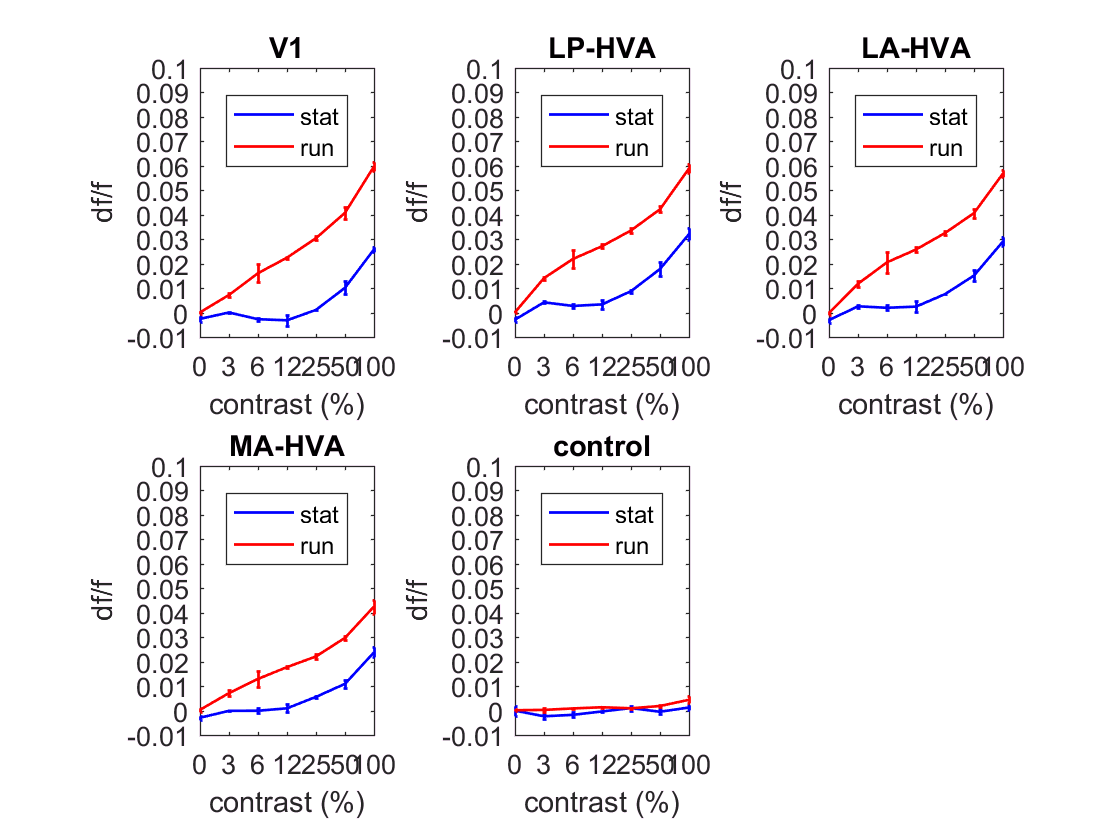

plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% LOCO (w/PUP)

% stat group CRF matrix
state = 'loRun'
clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeStatAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

% run group CRF matrix
state = 'hiRun'
clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)


yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT locomotion CRF 
stateLegend = {'stat','run'}
plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% CRF by PUPIL

% lo pup group CRF matrix
state = 'loPup'

state = loPup

clear loPup_allSessAllPtsAllDurs_CRF
[loPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoPupAllSessAllPtsAllDurs_CRF = size(loPup_allSessAllPtsAllDurs_CRF)

sizeLoPupAllSessAllPtsAllDurs_CRF =      1     7     5     3



% hi pup group CRF matrix
state = 'hiPup'

state = hiPup

clear hiPup_allSessAllPtsAllDurs_CRF
[hiPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiPupAllSessAllPtsAllDurs_CRF = size(hiPup_allSessAllPtsAllDurs_CRF)

sizeHiPupAllSessAllPtsAllDurs_CRF =      1     7     5     3



% crf pup figs 
stateLegend = {'loPup','hiPup'}

stateLegend =     'loPup'    'hiPup'


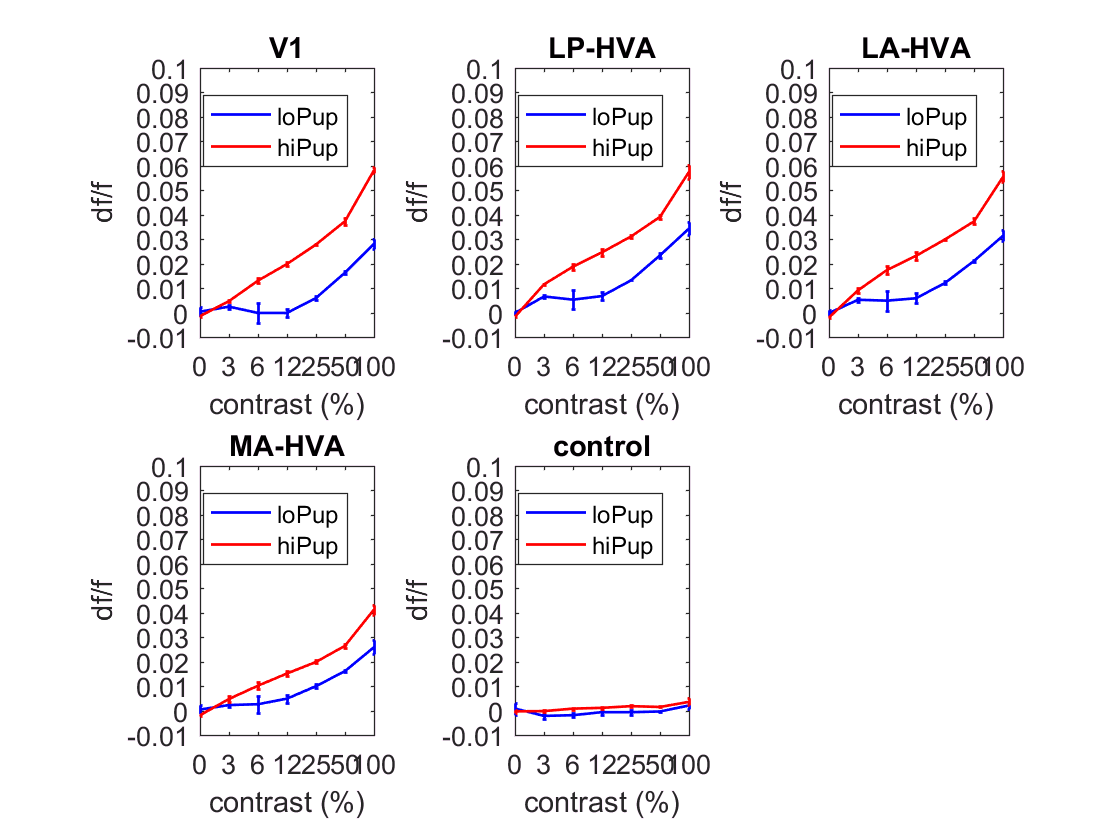

plotCompareBehState_CRF(loPup_allSessAllPtsAllDurs_CRF,hiPup_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% MEAN DF vs FRAMES (Q: why do both functions take both state inputs at same 
% time when each only outputs one or the other state....? A: b/c the function is for eiather
% beh state and needs both state trial idx inputs. Note: use GLOBAL next time

state = 'loRun'

state = loRun

[loRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoRun_mnTraceAllConsDursPts = size(loRun_mnTraceAllConsDursPts)

sizeLoRun_mnTraceAllConsDursPts =      7    18     1     5     3



state = 'hiRun'

state = hiRun

[hiRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiRun_mnTraceAllConsDursPts = size(hiRun_mnTraceAllConsDursPts)

sizeHiRun_mnTraceAllConsDursPts =      7    18     1     5     3



% for mean Trace figs

visArea = 1;
%visArea = 4;

%visArea = 1:length(groupRoundXpts{1,n})
durat = 1:length(uniqueDurations)

durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7



yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];

%x_axis = [1:length(uniqueContrasts)];
%xMax = max(x_axis);
%xMin = min(x_axis);
%xLimit = [xMin xMax];

% locomotion mean trace figs
stateLegend = {'stat','run'}

stateLegend =     'stat'    'run'


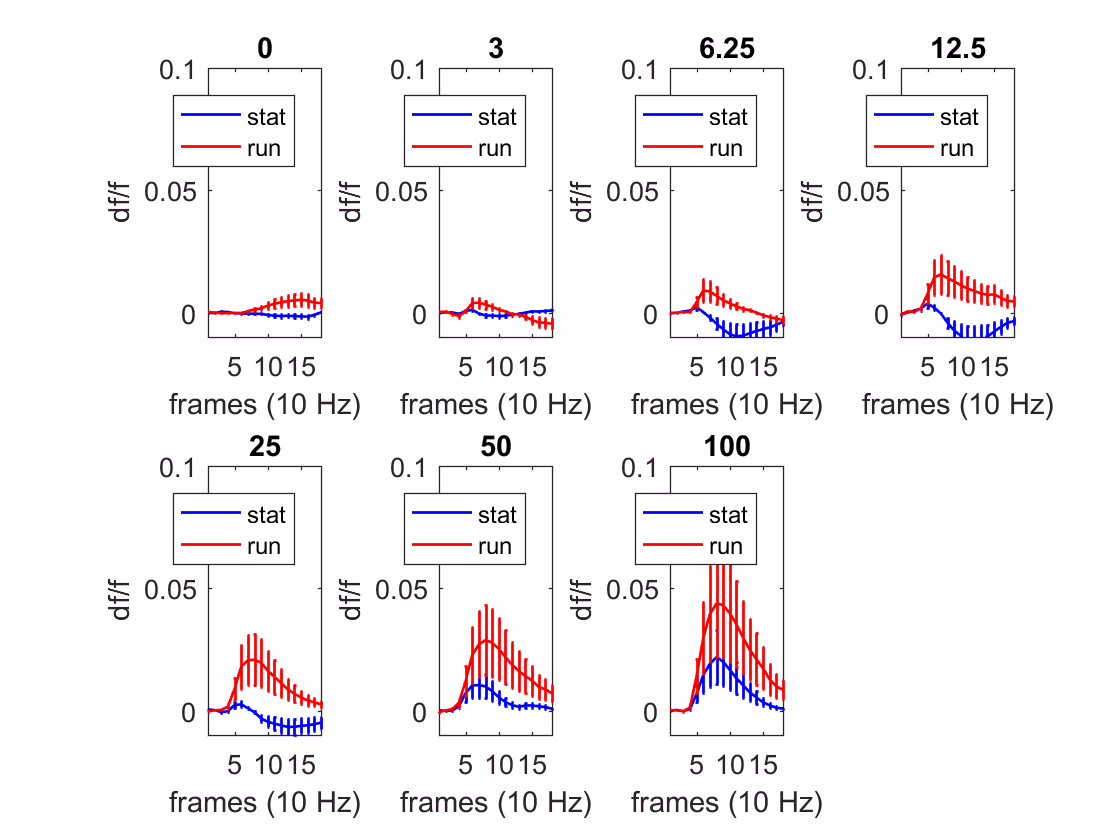

plotCompareBehState_mnTrace(loRun_mnTraceAllConsDursPts,hiRun_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% Mean Trace PUPIL
state = 'loPup'

state = loPup

[loPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoPup_mnTraceAllConsDursPts = size(loPup_mnTraceAllConsDursPts)

sizeLoPup_mnTraceAllConsDursPts =      7    18     1     1     3



state = 'hiPup'

state = hiPup

[hiPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiPup_mnTraceAllConsDursPts = size(hiPup_mnTraceAllConsDursPts)

sizeHiPup_mnTraceAllConsDursPts =      7    18     1     1     3



% pupil mean trace figs
stateLegend = {'loPup','hiPup'}

stateLegend =     'loPup'    'hiPup'


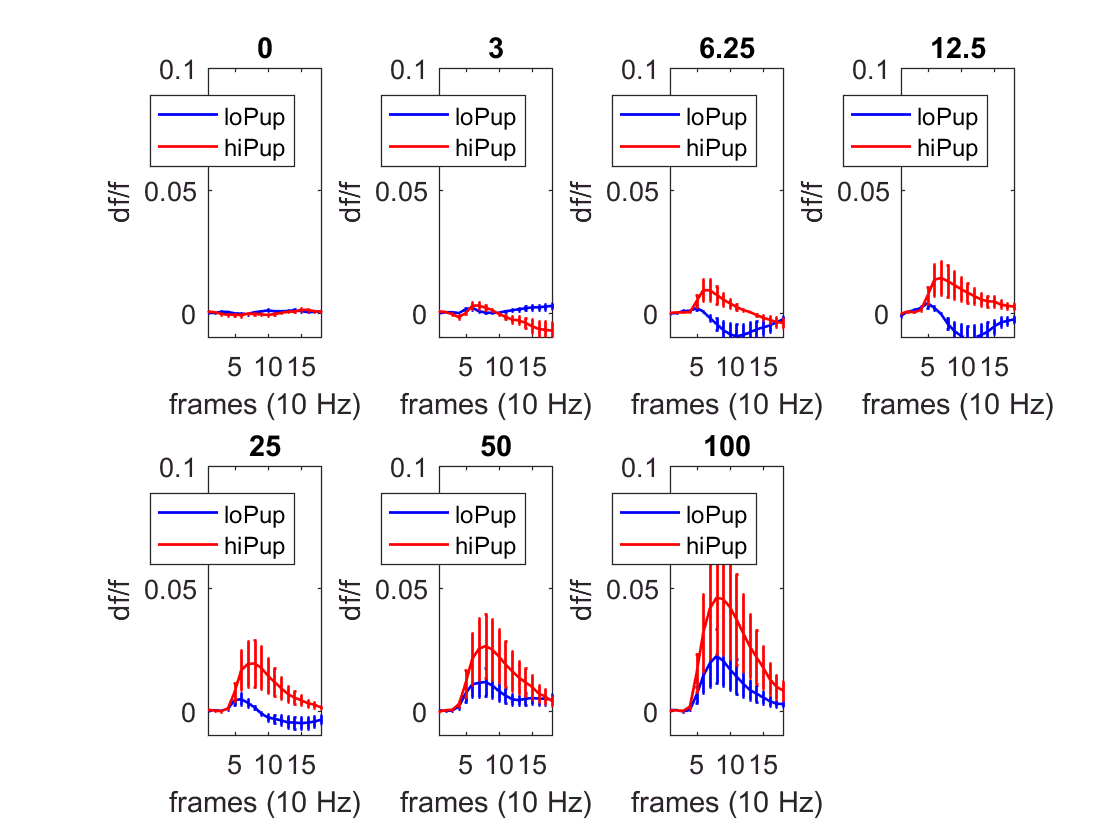

plotCompareBehState_mnTrace(loPup_mnTraceAllConsDursPts,hiPup_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)